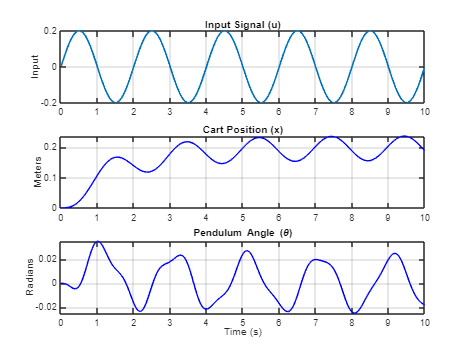

% SIMULATION each input
clear; clc; close all;

% 1. Define the Known Parameters
p.m = 0.1; 
p.M = 0.427;
p.l = 0.10382;
p.g = -9.81;

% 2. Define the "Secret" True Parameters
% Parameter that fmincon discover
J_true = 8.9432*10^-4; 
b_true = 0.35;

% 3. Build the True Mathematical Model
alpha = p.m + p.M - (p.m^2 * p.l^2) / (J_true + p.m * p.l^2);
beta = (J_true + p.m * p.l^2) - (p.m^2 * p.l^2) / (p.m + p.M);

A = [0 1 0 0;
     0, -b_true/p.M, -(p.m^2 * p.l^2 * p.g)/(alpha * (J_true + p.m * p.l^2)), 0;
     0 0 0 1;
     0, b_true/(p.M*p.l), (p.m * p.g * p.l)/beta, 0];
     
B = [0; 1/alpha; 0; -(p.m * p.l)/beta * (p.m + p.M)];
C = [1 0 0 0; 0 0 1 0]; 
D = [0; 0];

sys_true = ss(A, B, C, D);

% 4. Create the Sine Wave Experiment (DOE)
Ts = 0.01;              % 100 Hz sampling rate
t = (0:Ts:10)';         % Run the test for 10 seconds
freq_Hz = 0.5;          % 1 Hz sine wave
omega = freq_Hz * 2 * pi; 
amplitude = 0.2;        % Amplitude of the input force/voltage

% Generate the input sine wave
u_input = amplitude * sin(omega * t);

% 5. Simulate Hardware Response
y_perfect = lsim(sys_true, u_input, t);

% 6. Plot the Virtual Experiment
figure('Name', 'Virtual Hardware Data');
subplot(3,1,1); 
plot(t, u_input, 'LineWidth', 1.5); 
title('Input Signal (u)'); ylabel('Input'); grid on;

subplot(3,1,2); 
plot(t, y_perfect(:,1), 'b'); hold on;
title('Cart Position (x)'); ylabel('Meters'); 
grid on;

subplot(3,1,3); 
plot(t, y_perfect(:,2), 'b'); hold on;
title('Pendulum Angle (\theta)'); ylabel('Radians'); xlabel('Time (s)');
grid on;

PID control tuning

clf

t_vec = 0:0.01:1;

[num,den] = ss2tf(A, B, C, D, 1);
figure; 
disp("x")

x


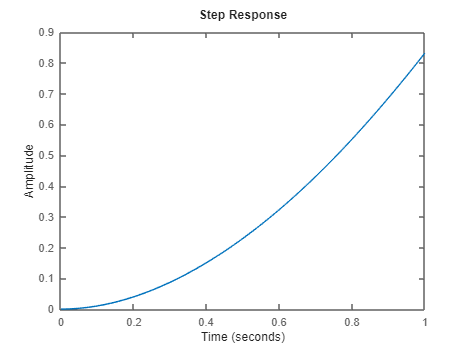

step(tf(num(1,:),den), t_vec)

disp("theta")

theta


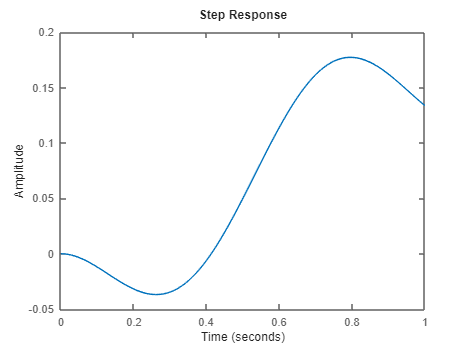

step(tf(num(2,:),den), t_vec)


disp("check for open loop stability by check ing eig(A)")

check for open loop stability by check ing eig(A)


stable = all(real(eig(A)) < 0);
if stable 
    fprintf("open loop is stable")
else 
    fprintf("not stable")

end

not stable

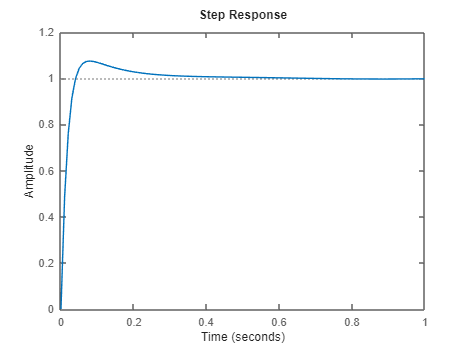



[num, den] = ss2tf(A, B, C, D, 1);
P = tf(num(1,:), den);          % cart position transfer function
P2 = tf(num(2,:), den);          % angkle of pendulum transfer function
Kp = 250; Ki = 10; Kd = 30;
C_pid = pid(Kp, Ki, Kd);

T = feedback(C_pid * P, 1);     % feedback() is negative by default
figure; step(T, t_vec);

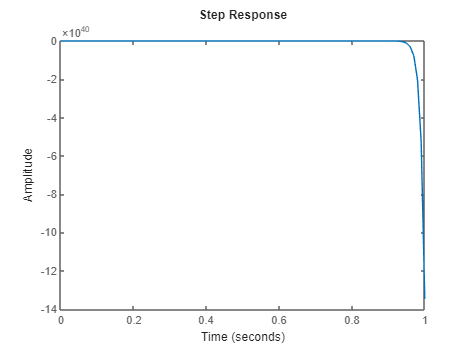



T2 = feedback(C_pid * P2, 1);     % feedback() is negative by default
figure; step(T2, t_vec);


disp("check for close-loop stability by checking eig(Acl)")

check for close-loop stability by checking eig(Acl)


[num_T, den_T] = tfdata(T, 'v');
[Acl,Bcl,Ccl,Dcl] = tf2ss(num_T,den_T);
stable = all(real(eig(Acl)) < 0);
if stable 
    fprintf("close loop is stable")
else 
    fprintf("not stable")

end

close loop is stable